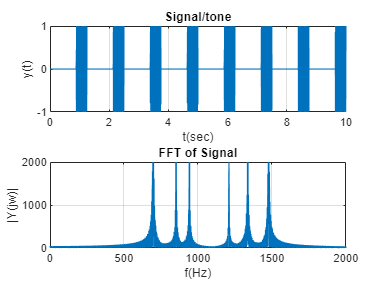

clear; clc; close;

% Problem 5:
filename = 'Test1.wav';
[y,Fs] = audioread(filename);
sound(y,Fs);
t = linspace(0,10,length(y));
pause(2);
y = double(y);
Len_y = length(y);
p = abs(fft(y));
f = (Fs/Len_y)*(1:Len_y);
figure; subplot(211); plot(t,y); grid 
title('Signal/tone'); ylabel('y(t)'); xlabel('t(sec)');
subplot(212); plot(f,p); title('FFT of Signal'); 
ylabel('|Y(jw)|'); xlabel('f(Hz)'); grid;
axis([0 2000 0 2000])

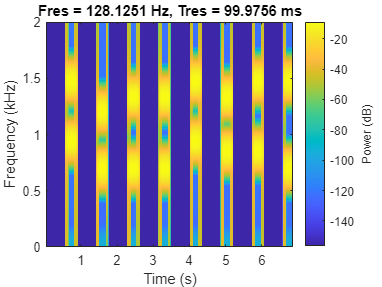

figure;
pspectrum(y,Fs,'spectrogram', ...
'FrequencyLimits',[0 2000],'TimeResolution',0.1)